# Introduction to MATLAB

## Author(s): Ronan Fleming, Leiden University

## Reviewer(s): 

## INTRODUCTION

*The purpose of this tutorial is to introduce a novice to progamming in MATLAB, with a view towards using the COBRA toolbox.*

## Good Laboratory Practice for computational work

**Reproducibility**

- computational results must be confirmed to be reproducible before anything is submitted for publication

- before anything is submitted for publication someone independent should check to confirm that your code can reproduce your results (including figures and tables) so make sure to construct a computational pipeline for each paper in a clear way with almost no manual steps (some exceptions e.g. install version x of some program)

- make sure everything is fully documented

Self contained

Understandable by others = used by others

Separation of data from code (functions, scripts, narratives)

Separation of raw data from computationally derived data

Separation of functions from scripts and narratives

## MATERIALS - EQUIPMENT SETUP

Please ensure that all the required dependencies (e.g. , `git` and `curl`) of The COBRA Toolbox have been properly installed by following the installation guide [here](https://opencobra.github.io/cobratoolbox/stable/installation.html). Please ensure that the COBRA Toolbox has been initialised (tutorial_initialize.mlx) and verify that the pre-packaged LP and QP solvers are functional (tutorial_verify.mlx).

## PROCEDURE

Define the directory of your project. Use a name like `projectFolderName`, with no spaces so one can easily naigate to it from a terminal. In this case, the location of the `matlabIntro` folder, which is unique to each person's system: 

%projectFolderPath='~/drive/2019_BioSB_Constraint-Based_Modelling_Course/materials/practicals/matlabIntro';
projectFolderPath='./matlabIntro'

projectFolderPath = './matlabIntro'

Recursively add all directories below a given path to the matlab path, so that matlab can find them:

addpath(genpath(projectFolderPath))

Check that the E. coli core model is accessible from the matlab path. This command should return the path to the E. coli core model:

which ecoli_core_model.mat

D:\code\semeco_explained\arxiv\ecoli_core_model.mat


This model should not be accessible and will give 'not found'

which NOT_ecoli_core_model.mat

'NOT_ecoli_core_model.mat' not found.


Change the current matlab folder to the matlabIntro folder

cd(projectFolderPath)

Ideally a project folder should be a locally synchronised copy of a folder on a cloud server, e.g., owncloud.org

#### (Computational) project organisation

Start organised, stay organised.

Observe the folder structure of this directory:

dir(projectFolderPath)

'./matlabIntro' not found. Check the path or file permissions.


**code**

Ideally, version controlled clone of a remote repositiory containing all code for a project.

e.g. implementation approach:

For each new project, one person leading a project should do this:

(1) set the desktop client for the cloud server to ignore folders named 'code'

(1) Create a new project folder by making a copy of a projectFolderTemplate, then give it a short name specific to the project, e.g., `thermoModel`

`$ mkdir ~/work/projects/thermoModel`

(2) Create a new repo with the name of the project folder.

e.g. @github.com

(3) Clone the new repo into the code folder for your new project`$ `

`$ cd ~/work/projects/thermoModel   `

`$ ``mkdir ``code  `

`$ ``git clone git@github.com:thermoModel.git code  `

This way, the rest of the project files are synced with a cloud server but version control is selectively used to sync the code for a project and both are kept together in the same project folder locally.

**literature** 

- books, papers, with the title as the name of the pdf

- bibliography management system for the citation key to be standard across papers

**conferences** 

- presentations at conferences

**data**

- all data used as input to a project in the exact form it was used without modification

- traceability

**results**

- computational results generated from a project, well organised in subfolders

- e.g. supplementary data, all figures and tables

- **DO NOT mix data with results**

**progressReports**

- Reports of progress to funding agencies

**meetings**

- record of meetings concerning a project, e.g., whiteboard images, or google docs link, cross reference to project specific thread, e.g. slack

**papers**

- scientific papers concerning a project

- narratives can be provided as supplementary material  

## MATLAB 

**Editor/Live editor:** 

% edit tutorial_intro_to_matlab.mlx

- scripts (.m) and narriatives (.mlx) are specific to a project

- scripts generate all their results as objects separate from the code

- narratives generate all their results as objects embedded with the corresponding code and textual descriptions, including (latex) equations, if necessary.

- narratives are very useful for generation of supplementary files (e.g. can also be exported as pdfs)

- functions (.m) - may be generated during a project but should be written in a way that they can be reused for other project and ultimately moved to a generic software suite, e.g., the COBRA toolbox

**Command window: **use for testing single lines, otherwise, for reproducibility, use narratives (live scripts)

For example, do a simple multiplication on the command line:

2*3

ans = 6

**Current folder:** files are accessible to matlab from this folder even if it has not been added to the matlab path. Check the current folder by typing the following into the command window:

pwd

ans = 'D:\code\semeco_explained\arxiv\matlabIntro'

**Workspace:** a workspace is a set of data currently accessible from within MATLAB. Make sure to show at least the following columns: Name; Value; Size; Class

whos

  Name                      Size                 Bytes  Class     Attributes

  Acomp                  2290x2290            41952800  double              
  Sbin                   2290x2991            54795120  double              
  ans                       1x42                    84  char                
  fileName                  1x13                    26  char                
  growthDel              2290x1                  18320  double              
  i                         1x1                      8  double              
  j                         1x1                      8  double              
  metConnectivity        2290x1                  18320  double              
  model_aux                 1x1                3988960  struct              
  projectFolderPath         1x13                    26  char                
  rxnID                     1x6                     48  double              
  rxnParticipation       2991x1                  23928  double             

Getting help: various approaches possible

1) MATLAB > Help

2) Enter is* into the search pane in the matlab help window to see many more.

3) [MATLAB Help website](https://uk.mathworks.com/help/matlab/index.html)

4) help functionName on the command line

help pwd

 pwd Show (print) current working directory.
    pwd  displays the current working directory.
 
    S = pwd returns the current directory in the string S.
 
    See also cd.

    Documentation for pwd



## PROGRAMMING

**Data representation**

Data is represented in MATLAB as "variables" with unique names (upto 63 characters) within each workspace.

Load a workspace (`.mat `file) into the current workspace containing a COBRA model. 

load 'ecoli_core_model.mat';

For reproducibility, do this programmatically rather than manually (point and click).

Note that the proper way to load a model into The COBRA Toolbox is to use the `readCbModel` function. For example, to load a model from a MAT-file, you can simply use the filename (with or without file extension). 

**Variables**

Like most other programming languages, the MATLAB language provides mathematical expressions, but unlike most programming languages, these expressions may involve entire matrices. 

MATLAB does not require any type declarations or dimension statements. 

When MATLAB encounters a new variable name, it automatically creates the variable and allocates the appropriate amount of storage. Preallocation of memory makes certain things more efficient, but is not essential.

If the variable already exists, MATLAB changes its contents and, if necessary, allocates new storage. For example, this code creates a double precision scalar (1-by-1 matrix) named `num_students` and stores the value 25 in its single element.

num_students = 25;

To view the data assigned to any variable, simply enter the variable name.

num_students

num_students = 25

Note that adding ; after a command supresses default output.

Variable names consist of a letter, followed by any number of letters, digits, or underscores. 

% 1badVariableName = num_students
goodVariableName1 = num_students;

MATLAB is case sensitive; it distinguishes between uppercase and lowercase letters. 

GoodVariableName1 = 'first_captial';

Confirm:

goodVariableName1

goodVariableName1 = 25

GoodVariableName1

GoodVariableName1 = 'first_captial'

The E. coli core metabolic model structure combines many of the classes of data used in MATLAB.

load 'ecoli_core_model.mat';
originalModel = model;

**Structures**

A `structure` is a multidimensional MATLAB arrays with elements accessed by textual `field` designators.

The contents of the E. coli core metabolic model structure can be seen line by entering the name of the variable corresponding to it, without a following semi-colon

model

model = struct with fields:
                rxns: {95×1 cell}
                mets: {72×1 cell}
                   S: [72×95 double]
                 rev: [95×1 double]
                  lb: [95×1 double]
                  ub: [95×1 double]
                   c: [95×1 double]
           metCharge: [72×1 int32]
               rules: {95×1 cell}
               genes: {137×1 cell}
          rxnGeneMat: [95×137 double]
             grRules: {95×1 cell}
          subSystems: {95×1 cell}
    confidenceScores: {95×1 cell}
       rxnReferences: {95×1 cell}
        rxnECNumbers: {95×1 cell}
            rxnNotes: {95×1 cell}
            rxnNames: {95×1 cell}
            metNames: {72×1 cell}
         metFormulas: {72×1 cell}
          metChEBIID: {72×1 cell}
           metKeggID: {72×1 cell}
        metPubChemID: {72×1 cell}
      metInchiString: {72×1 cell}
                   b: [72×1 double]
         description: 'ecoli_core_model'


The contents of the field name can be accessed by appending the field name to the structure name with a . in between.

To return a short description of the model

description = model.description

description = 'ecoli_core_model'

To return the size of the stoichiometric matrix

size(model.S)

ans =     72    95


#### Character arrays

A character array is a string of characters

newChar =  'EX_o2(e)' 

newChar = 'EX_o2(e)'

`newChar` is now the name of a variable of class character

newChar2 =  'EX_o2(e)' 

newChar2 = 'EX_o2(e)'

newChar2 is now also the name of a variable of class character.

A range of functions exist to test the class of a variable 

class(newChar)

ans = 'char'

ischar(newChar2)

ans = logical
   1


Character arrays can be concatenated

A = 'EX'

A = 'EX'

B = '_'

B = '_'

C = 'o2(e)'

C = 'o2(e)'

Concatenation

ABC = [A, B, C]

ABC = 'EX_o2(e)'

#### Numeric Arrays

Numeric Array: Scalar

num_students

num_students = 25

Numeric Array: Vector

lb = model.lb; 

lb is a column vector

size(lb)

ans =     95     1


Use the transpose operator to switch rows to columns

lb=lb';
size(lb)

ans =      1    95


Numeric Array: Matrix

S = model.S; 

By convention, the number of rows in S is equal to the number of metabolites, and number of columns is equal to the number of reactions:

[nMets,nRxns] = size(S)

nMets = 72

nRxns = 95

The spy function can be used to see a pictoral representation of S

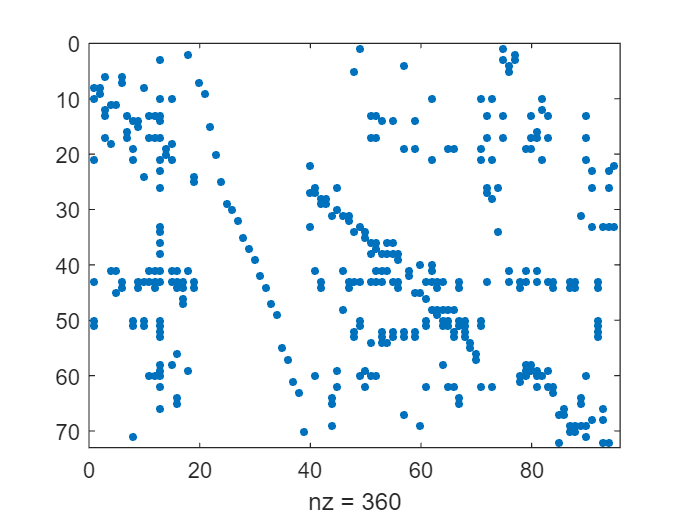

spy(S)

You can enter matrices into MATLAB in several different ways:

- Enter an explicit list of elements.

- Load matrices from external data files.

- Generate matrices using built-in functions. e.g. magic(3,4)

- Create matrices with your own functions in M-files.

Start by entering a matrix as a list of its elements. You only have to follow a few basic conventions:

- Separate the elements of a row with blanks or commas.

- Use a semicolon, ; , to indicate the end of each row. 

- Surround the entire list of elements with square brackets, [ ].

S = [-1 1; 1 -1]

S =     -1     1
     1    -1


Cell array

rxnNames = model.rxnNames

rxnNames = 95×1 cell array
    {'acetaldehyde dehydrogenase (acetylating)'                              }
    {'acetaldehyde reversible transport'                                     }
    {'acetate kinase'                                                        }
    {'aconitase (half-reaction A, Citrate hydro-lyase)'                      }
    {'aconitase (half-reaction B, Isocitrate hydro-lyase)'                   }
    {'acetate reversible transport via proton symport'                       }
    {'adenylate kinase'                                                      }
    {' 2-Oxogluterate dehydrogenase'                                         }
    {' 2-oxoglutarate reversible transport via symport'                      }
    {'alcohol dehydrogenase (ethanol)'                                       }
    {'ATP maintenance requirement'                                           }
    {'ATP synthase (four protons for one ATP)'                               }
    {'core E. coli biomas

`rxnNames` is now a variable name of class cell array containing reaction names in a model

Creating cell array

someArray = {'The' ; 'number'; 10}

someArray = 3×1 cell array
    {'The'   }
    {'number'}
    {[    10]}


Note that cell arrays can contain character arrays or numbers, whereas numeric arrays can only contain numbers.

There are different ways for accessing cell arrays.

Accessing the entries of arrays with numeric indexes (Note the {} brackets): 

aname = rxnNames{36}

aname = 'O2 exchange'

class(aname)

ans = 'char'

bool = false(nRxns,1);
bool(36) = 1;
aname2 = rxnNames{bool}

aname2 = 'O2 exchange'

class(aname2)

ans = 'char'

aname3 = rxnNames(bool)

aname3 = 1×1 cell array
    {'O2 exchange'}


class(aname2)

ans = 'char'

Accessing numeric arrays, e.g., upper and lower bounds on the O2 exchange reaction

model.lb(36)

ans = -1000

model.ub(36)

ans = 1000

same as 

lb = model.lb;
ub = model.ub;
lb(36)

ans = -1000

ub(36)

ans = 1000

same as

model.lb(bool)

ans = -1000

model.ub(bool)

ans = 1000

The Colon Operator

The colon : is one of the most important MATLAB operators. It occurs in several different forms. The expression `1:10 `is a row vector containing the integers from 1 to 10:

1:10 

ans =      1     2     3     4     5     6     7     8     9    10


 1     2     3     4     5     6     7     8     9    10

To obtain nonunit spacing, specify an increment. For example,

100:-7:50

ans =    100    93    86    79    72    65    58    51


Subscript expressions involving colons refer to portions of a matrix:

S(1:end,2)

ans =      1
    -1


Logical classes

The logical data type represents a logical true or false state using the numbers 1 and 0, respectively. 

Certain MATLAB functions and operators return logical true or false to indicate whether a certain  condition was found to be true or not. For example, the statement 50>40 returns a logical true value.

10 < 4

ans = logical
   0


Logical data does not have to be scalar; MATLAB supports arrays of logical values as well. 

r34 = rand(3,4)

r34 =     0.0664    0.3976    0.2982    0.7177
    0.6062    0.5934    0.3917    0.3071
    0.9235    0.0153    0.6054    0.1343


r34 > 0.5

ans = 3×4 logical array
   0   0   0   1
   1   1   0   0
   1   0   1   0


Logical indexing - the most powerful way to access any form of array. Find all the reactions which produce or consume oxygen

model.rxns{model.S(57,:)~=0}

ans = 'EX_o2(e)'

ans = 'O2t'

## Exercise 1: investigate the E. coli model

In the E. coli model, find all the metabolites produced and consumed in the 'glutamine synthetase' reaction?

What is the stoichiometry of the reaction?

### Operators/Scripts/Functions

clear
load ecoli_core_model.mat

#### Basic Command Syntax

A simple MATLAB command computes the result of the expression to the right of the equals sign and  assigns the value of the result to the output variable at the left. 

%edit templateFunction.m

The MATLAB software reserves certain words for its own use as keywords of the language, e.g., `is, and, for...`

Several functions return important special values that you can use in your M-files. e.g. NaN means Not a Number and helps to distinguish between no output and empty:

a = []


a =

     []



isempty(a)

ans = logical
   1


a = NaN;
isempty(a)

ans = logical
   0


isfinite(NaN)

ans = logical
   0


#### Operators

Arithmetic Operators - + ./ .* / * etc

Relational Operators == ~= <= < > >= 

Boolean operators & (and) | (or) ~ (not)

There is a big difference between "=" and "==". The former is an assignment operator, whilst the latter is a logical expression;

The examples shown in the following table use vector inputs A and B, where

A = [0 1 1 0 1];
B = [1 1 0 0 1];

The `&` operator Returns 1 for every element location that is true (nonzero) in both arrays, and 0 for all other elements.

A & B

ans = 1×5 logical array
   0   1   0   0   1


The `|` operator returns 1 for every element location that is true (nonzero) in either one or the other, or both arrays, and 0 for all other elements.

A | B

ans = 1×5 logical array
   1   1   1   0   1


The `~` operator gives the complement of each element of the input array, A.

~A

ans = 1×5 logical array
   1   0   0   1   0


#### Conditional Control

 `if, end, switch`

This group of control statements enables you to select at run-time which block of code is executed. 

Combined, "if" and "end" is the most basic form of flow control statement. The if statement evaluates  a logical expression and executes a group of statements when the expression is true. An end keyword, which matches the if, terminates the last group of statements. 

number = 1;
if number == 0
   path
end

Alternatively...

if number ~= 0
   path
end

		MATLABPATH

	D:\code\semeco_explained\arxiv\matlabIntro
	D:\code\semeco_explained\cobratoolbox\src\analysis\thermo
	D:\code\semeco_explained\cobratoolbox\src\analysis\thermo\componentContribution
	D:\code\semeco_explained\cobratoolbox\src\analysis\thermo\componentContribution\old
	D:\code\semeco_explained\cobratoolbox\src\analysis\thermo\directionalityReport
	D:\code\semeco_explained\cobratoolbox\src\analysis\thermo\directionalityReport\old
	D:\code\semeco_explained\cobratoolbox\src\analysis\thermo\experimentalData
	D:\code\semeco_explained\cobratoolbox\src\analysis\thermo\experimentalData\alberty2006
	D:\code\semeco_explained\cobratoolbox\src\analysis\thermo\experimentalData\ecoli
	D:\code\semeco_explained\cobratoolbox\src\analysis\thermo\experimentalData\metaboliteConcentrations
	D:\code\semeco_explained\cobratoolbox\src\analysis\thermo\experimentalData\transport
	D:\code\semeco_explained\cobratoolbox\src\analysis\thermo\experimentalDesign
	D:\code\semeco_explained\cobratoolbox\src

Note that `path` is a call to a function with no argument supplied

Below "number" is a variable, but "path" is a function. This can be overridden, but its not a good idea to mix the names of variables/scripts/functions even though they are arbitrary.

path=number;
path

path = 1

clear path
path

		MATLABPATH

	D:\code\semeco_explained\arxiv\matlabIntro
	D:\code\semeco_explained\cobratoolbox\src\analysis\thermo
	D:\code\semeco_explained\cobratoolbox\src\analysis\thermo\componentContribution
	D:\code\semeco_explained\cobratoolbox\src\analysis\thermo\componentContribution\old
	D:\code\semeco_explained\cobratoolbox\src\analysis\thermo\directionalityReport
	D:\code\semeco_explained\cobratoolbox\src\analysis\thermo\directionalityReport\old
	D:\code\semeco_explained\cobratoolbox\src\analysis\thermo\experimentalData
	D:\code\semeco_explained\cobratoolbox\src\analysis\thermo\experimentalData\alberty2006
	D:\code\semeco_explained\cobratoolbox\src\analysis\thermo\experimentalData\ecoli
	D:\code\semeco_explained\cobratoolbox\src\analysis\thermo\experimentalData\metaboliteConcentrations
	D:\code\semeco_explained\cobratoolbox\src\analysis\thermo\experimentalData\transport
	D:\code\semeco_explained\cobratoolbox\src\analysis\thermo\experimentalDesign
	D:\code\semeco_explained\cobratoolbox\src

The optional elseif and else keywords provide for the execution of alternate groups of statements.

A = 0.5;
B = rand(1)

B = 0.5206

if A > B
   'greater'
elseif A < B
   'less'
elseif A == B
   'equal'
end

ans = 'less'

 To select from a number of possible options depending on the value of an expression, use the  `switch` and `case` statements (which may include otherwise).

e.g. Load data into matlab depending on the numerical value of "number"

number = 2;
switch number
    case 1
        %matlab structure
        load(which('ecoli_core_model.mat'))
        disp(model.description)
    case 2
        disp('wrong number')
end

wrong number


#### Loop Control

`for, while, break.`

With loop control statements, you can repeatedly execute a block of code, looping back through the  block while keeping track of each iteration with an incrementing index variable. 

Use the for statement to loop a specific number of times.  The for loop executes a statement or group of statements a predetermined number of times. Its syntax is

`for index = start:increment:end`

`   statements`

`end`

The default increment is 1. You can specify any increment, including a negative one. For positive indices, execution terminates when the value of the index exceeds the end value; for negative increments, it terminates when the index is less than the end value. 

For example, this loop executes five times.

x=2;
for n = 2:6
    x(n) = 2 * x(n - 1);
end

You can nest multiple for loops.

for m = 1:5
    for n = 1:6
        A(m, n) = 1/(m + n - 1);
    end
end

The while statement is more suitable for basing the loop execution on how long a condition continues to be true or false. The while loop executes a statement or group of statements repeatedly as  long as the controlling expression is true (1). Its syntax is

`while expression`

`     statements`

`end`

For example, this while loop finds the first integer n for which n! (n factorial) is a 20-digit number.

n = 1;
while prod(1:n) < 1e20
    n = n + 1;
end
disp(n)

Exit a while loop at any time using the break statement.

n = 1;
while prod(1:n) < 1e20
    n = n + 1;
    if n > 10
        break;
    end
end
disp(n)

#### Internal MATLAB Functions

Many of the functions provided with the MATLAB software are implemented as M-files just like the  M-files that you will create with MATLAB. Other MATLAB functions are precompiled executable programs called built-ins that run much more efficiently. 

If you are wondering if a function is already provided with your matlab distribution, then the easiest way to find it is to use the matlab help browser

% docsearch

Ideally each function is given a unique name, however, sometimes, certain function names are reused. The use of an unintended version of a function is a rare problem, but difficult to spot when it occurs.

Usually, you will not notice something working correctly. When other issues have been ruled out, it is useful to rule out the possibility that one is using an incorrect version of a function

which -all initCobraToolbox

This lists all the versions of functions named `initCobraToolbox` in your matlab installation, after the current path, the version used is the first in this list.

#### Custom MATLAB functions.

The COBRA toolbox is but one example of a suite of custom matlab functions. There are thousands of custom functions generated by others online at matlab central file exchange [http://www.mathworks.com/matlabcentral/fileexchange/](http://www.mathworks.com/matlabcentral/fileexchange/)

Functions vs Scripts vs Narriatives (live scripts)

When you write a MATLAB function or script, you save it to a file called an M-file (named after its .m file extension).

When you write a MATLAB narritive (live script), you save it to a file with a suffix .mlx

Feedback to the command line, most simply with the command

disp('some feedback')

is essential to keep an eye on the progres of the function. Similarly, writting comments into the code is essential for quickly understanding what is going on, especially at a later date, when one might have forgotten what the function was for. Note the description of input and output, these will allow other users to uitilize the code, even if they are not totally familiar with the inner details.

## TROUBLESHOOTING

*There are three types of things that can go wrong:*

#### *Errors*

*Errors cause MATLAB to stop execution and no further commands are evaluated. For example, *

[nMets, nRxns] = size(model.S)
% model.S(nMets+1,nRxns)

will return red writing saying "Index exceeds array bounds." which means that we tried to evaluate a stoichiometric coefficient in the 73rd row of the stoichiometric matrix, but there are only 72 rows in it so an error returns.

MATLAB comes with a powerful graphical debugging facility that will help to track down the source of errors. Essentially, the idea is to pause the evaulation on the line before an error is thrown and work backwards to investigate, i.e., debug, the preceeding code. 

#### Warnings

Warnings also return red text but are an indication that something is not exactly right but matlab can proceed with evaluating further lines by making some assumption, though it is wise to check where the warning was initiated from and adjust ones code to avoid it.

#### Logical errors

A logical error is when the code evaluates fine but the actual evaulation does not correspond to what the programmer had intended. i.e. it is a mistake by the programmer, that is still evaluatable by matlab, but not an intended computational action. These mistakes are the hardest to find. 

One way to combat logical errors is to add lots of **sanity checks** to the code, e.g., if something does not work as expected, there should be some lines of code to check for this and either issue a warning or an error if there is a problem. This allows a user to straight away find the origin of a problem what would otherwise be propagated downstream, making it much harder to track back to the problem(s).

## TIMING

*1 hr for a beginner.*

## ANTICIPATED RESULTS

*Beginners knowledge of matlab, esp those parts important for starting to use the COBRA toolbox.*

## *Acknowledgments*

*Please note an acknowledgments section can be included.*

## REFERENCES

Laurent Heirendt & Sylvain Arreckx, Thomas Pfau, Sebastian N. Mendoza, Anne Richelle, Almut Heinken, Hulda S. Haraldsdottir, Jacek Wachowiak, Sarah M. Keating, Vanja Vlasov, Stefania Magnusdottir, Chiam Yu Ng, German Preciat, Alise Zagare, Siu H.J. Chan, Maike K. Aurich, Catherine M. Clancy, Jennifer Modamio, John T. Sauls, Alberto Noronha, Aarash Bordbar, Benjamin Cousins, Diana C. El Assal, Luis V. Valcarcel, Inigo Apaolaza, Susan Ghaderi, Masoud Ahookhosh, Marouen Ben Guebila, Andrejs Kostromins, Nicolas Sompairac, Hoai M. Le, Ding Ma, Yuekai Sun, Lin Wang, James T. Yurkovich, Miguel A.P. Oliveira, Phan T. Vuong, Lemmer P. El Assal, Inna Kuperstein, Andrei Zinovyev, H. Scott Hinton, William A. Bryant, Francisco J. Aragon Artacho, Francisco J. Planes, Egils Stalidzans, Alejandro Maass, Santosh Vempala, Michael Hucka, Michael A. Saunders, Costas D. Maranas, Nathan E. Lewis, Thomas Sauter, Bernhard Ø. Palsson, Ines Thiele, Ronan M.T. Fleming, **Creation and analysis of biochemical constraint-based models: the COBRA Toolbox v3.0**, Nature Protocols, volume 14, pages 639–702, 2019 [doi.org/10.1038/s41596-018-0098-2](https://doi.org/10.1038/s41596-018-0098-2).